# Temperature Dependence of Absorption Spectrum

Author: André Silva Correia

## Initialisation

LIFSIM_path = "C:\Users\andresilvacorr\OneDrive - Delft University of Technology\PhD\LIFSIM\LIFSim";
init;

### Species

species = "NO";
colls_path = "C:\Users\andresilvacorr\OneDrive - Delft University of Technology\PhD\LIFSIM\LIFSim\input-data\gas-compositions\air+NO.csv";

### Flame Characteristics

    Tflame - flame temperature profile at different $\phi$

    Y_species - target species molar concentration

    phi - equivalenc ratio $\phi$

load("input-data/gas-compositions/F_PLIF_OH_NO.mat");
ph = phi(4);    % Flame equivalence ratio

### Temperature Range [K]

Tstep = 100;
Trange = [1100 2100];
Tset = Trange(1):Tstep:Trange(2);

### Laser parameters

unit = 'nm';
%224.97 - 225.22 ~ 44400 - 44450
startwn = 224 ;
checkWnum(unit,startwn);
endwn = 227;
checkWnum(unit,endwn);
step = 0.0001;
dnuGL = 0.001;    % Laser FWHM Gaussian
dnuLL = 0.001;    % Laser FWHM Lorentzian
I_filter = 0.55;    % Filter out lines without sufficient itensity to be detected

### Environment

N = 1;        % Number density [1/m^3]
L = 0.05;        % Path length [m]
P = 1;        % Pressure [bar]

dnuL = 0.01;
dnuSh = 0;

Tenv =  1800;    % Environment Temperature to analyse the itensities to be filtered [k]

### Plot Settings

num_lines = 5;

## **Collisions data and Absorption spectrum filter**

colls =  collisions(species);

absWnum = startwn:step:endwn;
plotWnum = absWnum;

if strcmpi(unit,'nm') 
    absWnum = convWnumWlen(absWnum);
    dnuGL = convWnumWlen(dnuGL,endwn);
    dnuLL = convWnumWlen(dnuLL, endwn);
end

[aux_linelist, Z, n, ~,MM] = selectLines(species,absWnum);

if n == 0    
    warning("No lines found.")
    return;
end

if ~isempty(colls)
    gas = loadGasComposition(colls_path);
    
    [dnuL, dnuSh] = collisionalBroadening(gas, colls, P, Tenv);
    [quen,aux_linelist] = quenchRate(gas, colls, Tenv, P,MM, aux_linelist);
 
end
varargin   = {'Z', Z};

aux_spec = absorptionSpec(absWnum, aux_linelist, MM, Tenv, dnuGL, dnuLL,Z=Z,...
      limit=12, N=N, L=L, dnuL=dnuL, dnuSh=dnuSh, normalize=false);


I_thresh = I_filter*max(aux_spec);
[aux_spec_peak, aux_absWnum_peak, peakWidths] = findpeaks(aux_spec, absWnum);

linelist = {};
for i = 1:size(aux_spec_peak,2)
    if aux_spec_peak(i) >= I_thresh
        for j = 1:size(aux_linelist,1)            
            if (aux_linelist{j}.nu0 >= (aux_absWnum_peak(i)-peakWidths(i))) && (aux_linelist{j}.nu0 <= (aux_absWnum_peak(i)+peakWidths(i)))
                linelist = [linelist; aux_linelist{j}];
            end
        end
    end
end


## **Absorption spectrum**

for i = 1:size(Tset,2)
    if ~isempty(colls)
        gas = loadGasComposition(colls_path);
        
        [dnuL, dnuSh] = collisionalBroadening(gas, colls, P, Tset(i));
        [quen,linelist] = quenchRate(gas, colls, Tset(i), P,MM, linelist);
     
    end
    varargin   = {'Z', Z};
    
    aux_spec = absorptionSpec(absWnum, linelist, MM, Tset(i), dnuGL, dnuLL,Z=Z,...
          limit=12, N=N, L=L, dnuL=dnuL, dnuSh=dnuSh, normalize=false);
    
    if i == 1
        [spec_peak(i,:), absWnum_peak(i,:)] = findpeaks(aux_spec, absWnum, "MinPeakHeight",I_thresh*0.085);
    else
        [aux_spec_peak, aux_absWnum_peak] = findpeaks(aux_spec, absWnum, "MinPeakHeight",I_thresh*0.085);
        peak_dist = pdist2(aux_absWnum_peak(:), absWnum_peak(i-1,:)');
        [aux_r, aux_c] = find(peak_dist < 2*dnuL);
        spec_peak(i,:) = aux_spec_peak(aux_r);
        absWnum_peak(i,:) = aux_absWnum_peak(aux_r);
    end
    

    if strcmpi(unit,'nm') 
        aux_spec = fliplr(aux_spec);
    end
    spec(i,:) = aux_spec;

end


## Temperature Dependence

Temperature Dependence weighted average:


$${\left\langle \left|\frac{\textrm{dF}\left(T_{i\;} ,\lambda_j \right)}{{\textrm{dT}}_i }\right|\right\rangle }_{N_{\textrm{species}} }$$


i_flame = find(phi == ph);

[~, aux_i] = unique(Tflame{i_flame});
Tflame{i_flame} = Tflame{i_flame}(aux_i);

switch species
    case "OH"
        Y_OH{i_flame} = Y_OH{i_flame}(aux_i);
        Y_species = interp1(Tflame{i_flame},Y_OH{i_flame},Tset,'spline');
        Y_species(Y_species<0) = 0;
    case "NO"
        Y_NO{i_flame} = Y_NO{i_flame}(aux_i);
        Y_species = interp1(Tflame{i_flame},Y_NO{i_flame},Tset,'spline');
        Y_species(Y_species<0) = 0;
end

for i = 1:size(absWnum_peak,2)
    dI(i) = sum(abs(diff(spec_peak(:,i)')./diff(Tset)).*Y_species(2:end))/trapz(Y_species(2:end));
end

[dI, aux_i] = sort(dI);
absWnum_peak = absWnum_peak(:,aux_i);
spec_peak = spec_peak(:,aux_i);

## Result

### Plot

T_plot_norm = (Tset -Trange(1))/(Trange(2) -Trange(1));

figure
hold on

for i = 1:size(Tset,2)-1
    color = turbo(256);
    line_color = color(round(T_plot_norm(i) * 255) + 1, :);
    % Connect the points with plot
    plot(plotWnum, spec(i,:), 'Color', line_color, 'LineWidth', 0.5);
end

grid
colormap(gca,"turbo")
cb = colorbar();
ylabel(cb,'Temperature [K]')
clim([min(Tset) max(Tset)])
ylim([-0.1*max(spec_peak,[],'all') inf])
xlim([startwn endwn])
xlabel('Wavenumber [nm]');
ylabel('Absorbance [ln(I/I0)]');

### Least dependant on Temperature:

for i=1:min([size(absWnum_peak,2) num_lines])
    fprintf('%d: %.2f cm-1 = %.3f nm\n', i, absWnum_peak(1,i), convWnumWlen(absWnum_peak(1,i)));
    fprintf('    dI_dT = %.2f \n', dI(i)/dI(1));
    plot(convWnumWlen(absWnum_peak(1,i)),max(spec_peak(:,i)),'ko','MarkerSize',10)
    text(convWnumWlen(absWnum_peak(1,i)),-0.05*max(spec_peak,[],'all'),sprintf("%d",i),'HorizontalAlignment','center','VerticalAlignment','middle')
end

1: 44401.05 cm-1 = 225.220 nm


    dI_dT = 1.00 


2: 44480.86 cm-1 = 224.816 nm


    dI_dT = 1.20 


3: 44420.67 cm-1 = 225.120 nm


    dI_dT = 1.22 


4: 44332.45 cm-1 = 225.568 nm


    dI_dT = 1.63 


5: 44345.58 cm-1 = 225.502 nm


    dI_dT = 1.72 


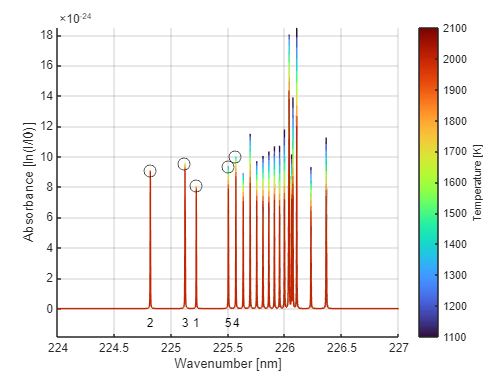


hold off